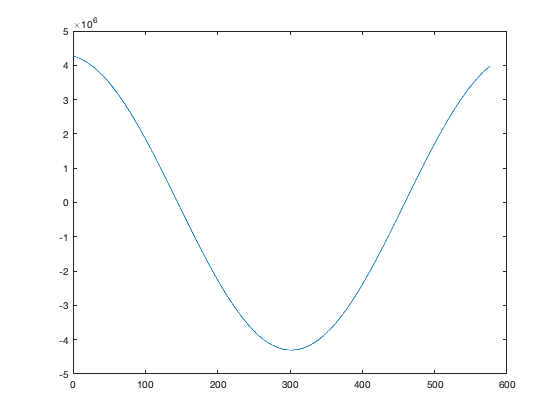

N = 64;     % block size
nBlocks = 10;

rng = 1:(N*nBlocks);
rngs=1:N;

data1=cos(rng.*0.01);
data2=rngs .* rngs .* rngs;

% do convolution

convolved = conv(data1,data2,'valid');
plot(convolved);

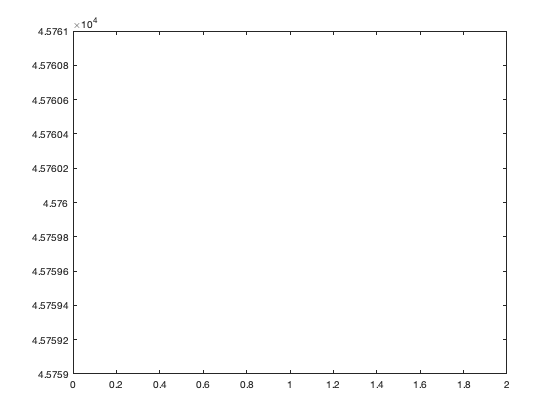

d1 = 1:N;
d2 = 1:N;

cv= conv(d1,d2,'valid');
plot(cv);

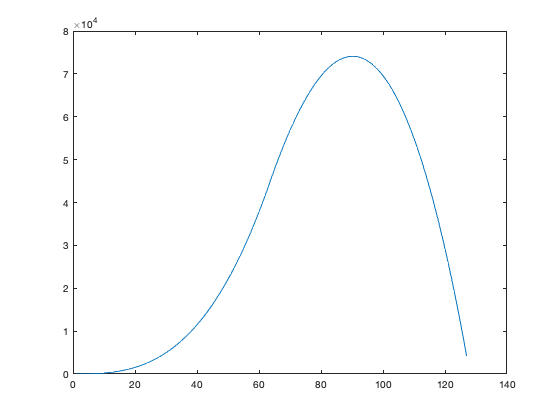


z = zeros(1,N);
x1 = zeros(1,2*N);
x2 = zeros(1,2*N);
x2(1:N) = d2(1:N);
x1((N+1):(2*N))=d2(1:N);

f1=fft(x1);
f2=fft(x2);
co = ifft(f1 .* f2);
cc = cat(2,co((N+1):(2*N)),co(1:N));
cc = cc(1:(2*N-1));
plot(cc);


di = cc-cv;
ma = max(di)

ma = 2.8340e+04

mi = min(di)

mi = -4.5759e+04


buffer2 = zeros(1,N*2);
buffer2(1:N) = data2;
f2 = fft(buffer2);

range = (N+1):(N*2);

outs = zeros(1,N*nBlocks);

buffer1 = zeros(1,N*2);
for chunk = 0:(nBlocks-1)
    offset=1+chunk*N;
    last=offset+N-1;
    buffer1(1:N) = buffer1(range);
    buffer1(range) = data1(offset:last);
    
    f1 = fft(buffer1);
    fp = f1 .* f2;
    out = ifft(fp);
    st = N*chunk+1;
    en = N*(chunk+1);
    outs(st:en) = out((N+1):N*2);
end

outs=outs(N:(N*nBlocks));

plot(outs);


di = convolved-outs;
ma = max(di)

ma = 1.8626e-09

mi = min(di)

mi = -2.3283e-09